# 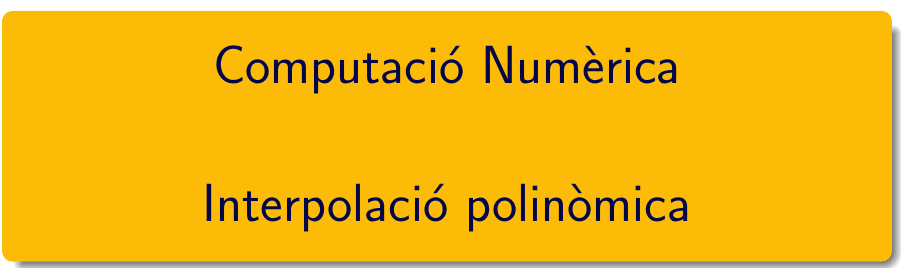

================================================================================

# Pràctica 6 - Interpolació polinònimca i ajust de dades (I)

`document preparat per M. Àngela Grau Gotés - març 2023`

## $\bullet$APRENEM .....Bloc1

### Polinomis i MATLAB®

Consulteu la pàgina [crear y evaluar polinomios](https://es.mathworks.com/help/matlab/math/create-and-evaluate-polynomials.html) y la pàgina [Raíces de polinomios](https://es.mathworks.com/help/matlab/ref/roots.html), ambdues de la documentació de MATLAB®. També us pot interesar la pàgina [Integrar y diferenciar polinomios](https://es.mathworks.com/help/matlab/math/integrate-and-differentiate-polynomials.html).

Després de llegir els dos primers documents, calculeu:

- les arrels del polinomi cúbic (grau 3)  $x^3+4x^2+4x=0$ 

- avalueu el polinomi  $x^5-1$ per $x=2$

- coficients del polinomi d'arrels els enters  -5,-2, -1, 1, 2, i 8. Quin grau té?

                 % vector amb els coeficients del polinomi 
                 pol1 = [1 4 4 0];
                 % arrels

arrels =      0
    -2
    -2


                 arrels = roots(pol1)
                 % vector amb els coeficients del polinomi 
                 pol2 = [1 0 0 0 0 -1];
                 % valor polinomi

val =     31


                 val = polyval(pol2, 2)
                 % vector amb les arrels
                 r = [-5 -2 -1 1 2 8];
                 % coeficients polinomi d'arrels r

pol3 =      1    -3   -45    15   204   -12  -160


                 pol3 = poly(r)

### Polinomi interpolador (matriu de Vandermonde)

Els coeficients del polinomi interpolador s'obtenen resolent el sistema lineal corresponent: amb matriu del sistema la matriu de Vandermonde.

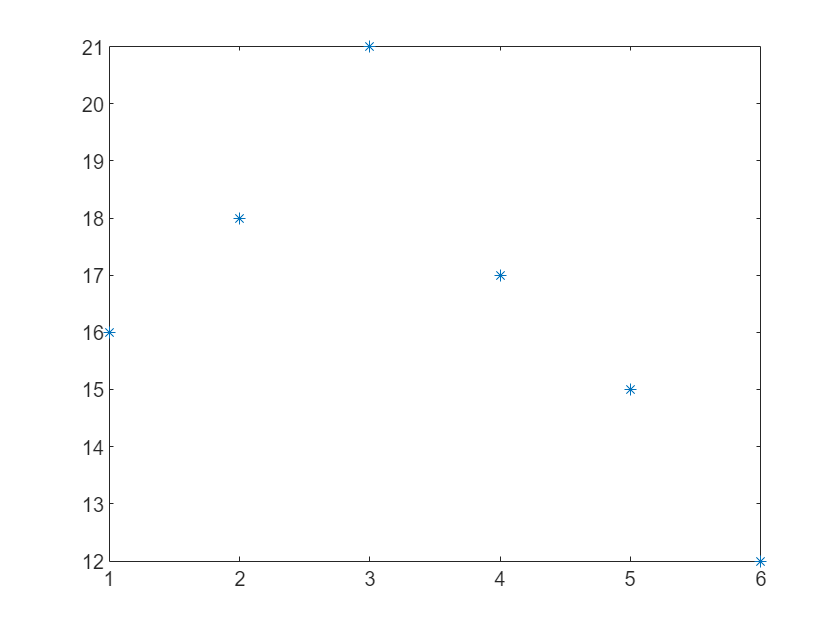

x = 1:6;
y = [16 18 21 17 15 12];    

plot(x,y,'*')
 


### Polinomi interpolador (fórmula de Lagrange)

Baixeu-vos del campus el codi de polyinterp.m. Aquest codi és el que C. Moler explica en el chapter 3 dels seus apunts *"*[*Numerical Computing with Matlab*](https://www.mathworks.com/moler/chapters.html)*". *

x = [0,1,2,3];
y = [-5 -6 -1 16];
u = linspace(0, 3, 10);

Unrecognized function or variable 'polyinterp'.

La rutina polyinterp.m s'obtenen els valors del polinomi interpolador a la taula [x;y] i permet fer la seva representació gràfica. En cap cas obtenim els coeficients del polinomi interpolador. 

`Exemple 1`` - Llista de problemes, exercici 1`. 

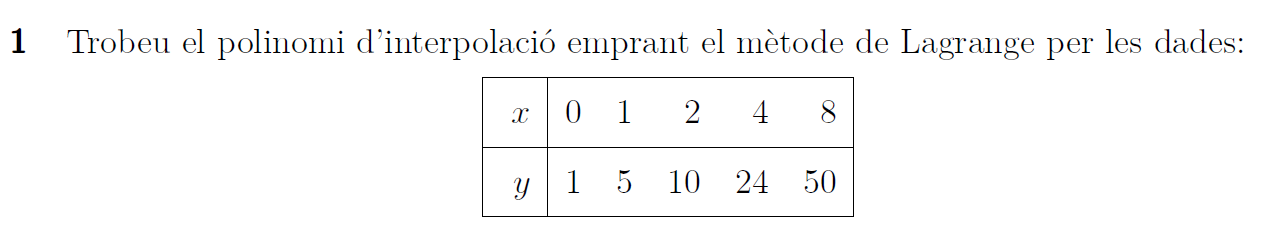

 v = polyinterp(x, y, u);
plot(x,y,'o',u,v,'-')


### Polinomi interpolador (diferències dividides de Newton)

`Exemple 2`` - Llista de problemes, exercici 2`. 

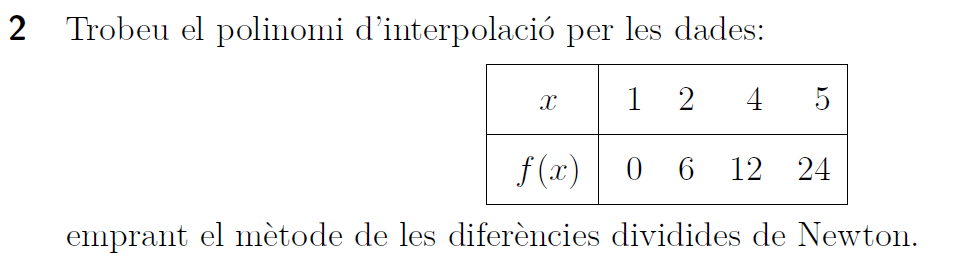

Baixeu-vos el codi de MATLAB fileEchange [codi diferències dividides](https://es.mathworks.com/matlabcentral/fileexchange/105325-matlab-functions-for-numerical-interpolation-methods)

clearvars
x = [1 2 4 5];
y = [0 6 12 24];


### Funció de MATLAB®

Els coeficients del polinomi interpolador es poden obtenir amb polyfit, i els valors aproximats amb polyval. Consulteu [polyfit](https://es.mathworks.com/help/matlab/ref/polyfit.html)

`Exemple 3`` - Canvi d'escala` 

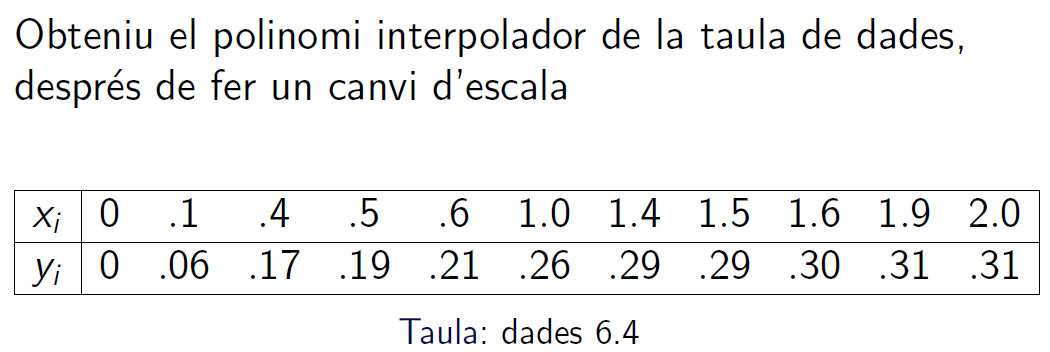

x = [0 .1 .4 .5 .6 1.0 1.4 1.5 1.6 1.9 2.0];
y = [0 .06 .17 .19 .21 .26 .29 .29 .30 .31 .31];
p = polyfit(x, y, 3)

`OBSERVACIÓ - polyinterp de Moler = polyfit + polyval de MATLAB`

## $\bullet$PRACTIQUEM ....

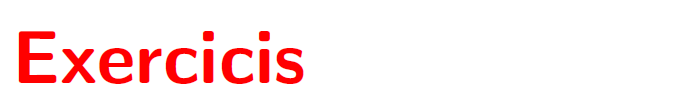

### Exercici 1

Aquest exercici s'ha de resoldre fent ús de polinomis de Lagrange,  **polyinterp**

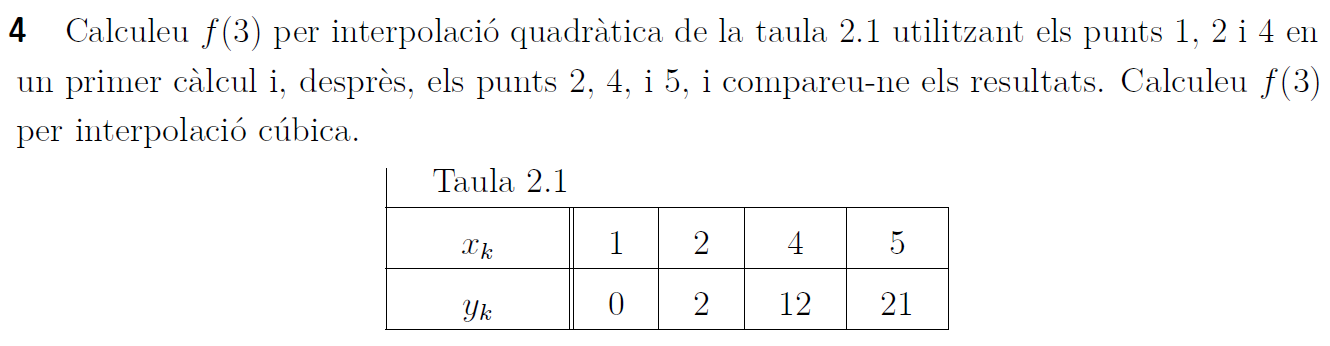

clearvars
x = [1 2 4 5]; y = [0 2 12 21];

- primer càlcul

x1=x(1:3);  y1=y(1:3)
valor = polyinterp(x1,y1,3);
disp(['valor1 =',num2str(valor)])

- segon  càlcul

x2=x(2:4);  y2=y(2:4)
valor = polyinterp(x1,y1,3);
disp(['valor1 =',num2str(valor)])

- tercer  càlcul

p = polyfit(x, y, 3)
val = polyval(p, 3)

### Exercici 2

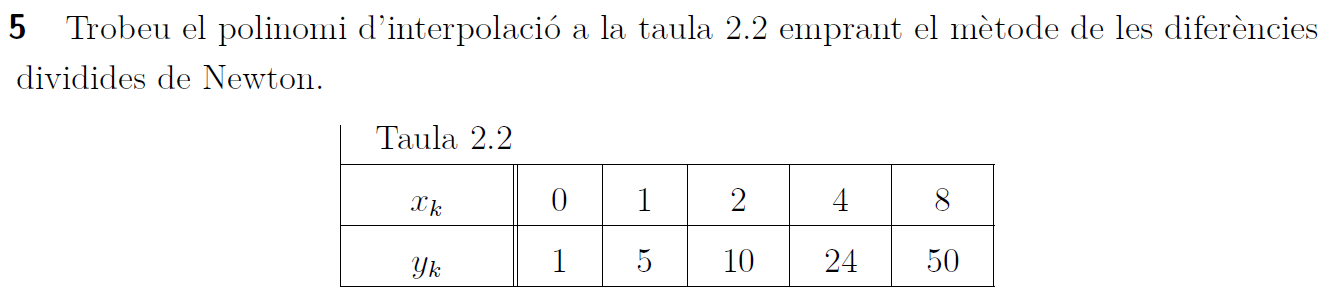

clearvars; clf
x = [0 1 2 4 8]; y = [0,5 10 24 50];
disp([x; y])
 

### Exercici 3

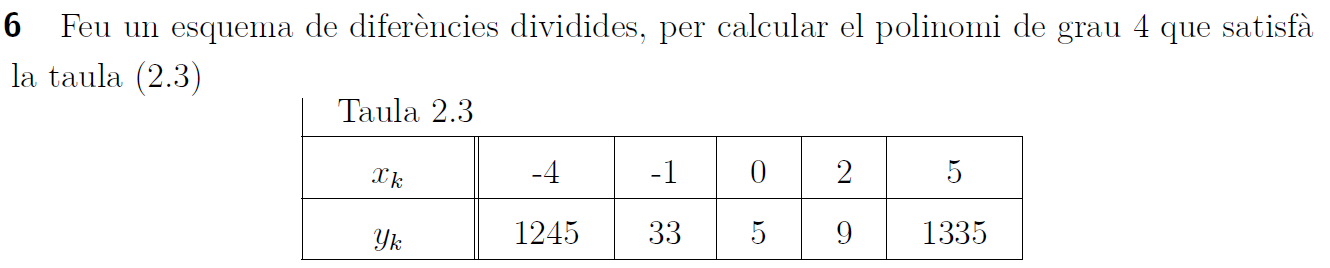

clearvars; clf
x = [-4 -1 0 2 5]; y = [1245 33 5 9 1335];
disp([x; y])


### Exercici 4. Interpolació inversa

Aplicació de la interpolació al càlcul de zeros de funcions (`Interpolació inversa`)

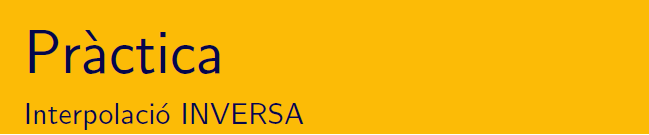

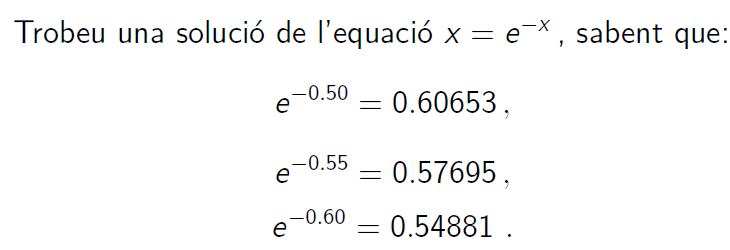


x = [0.5:0.05:0.6];
y = x-exp(-x);
disp([x; y]')
%La interpolació inversa es basa en realitzar una interpolació de la funció
%inversa en comptes de l'original. En aquest cas, en comptes de x = e^-x, x
%= -lnx. Les x -> y, i les y -> x
x_n =  [0.60653, 0.57695, 0.54881];
y_n = [0.5, 0.55, 0.6];
% Interpolación inversa
p = polyfit(x_n, y_n, 2); % Ajuste polinomial de grado 2

% Encontrar la solución aproximada
x_aprox = polyval(p, 1);

disp("La solución aproximada mediante interpolación inversa es:");
disp(x_aprox);

### Exercici 5. Comportament de l'error en la interpolació polinòmica

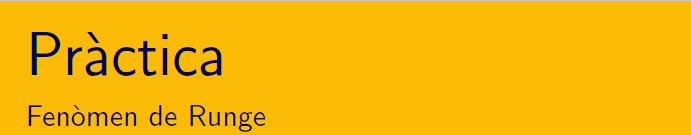

Baixeu-vos del campus el codi de rungeinterp.m. Aquest codi és el que C. Moler explica en el chapter 3 dels seus apunts *"Numerical Computing with Matlab". *Consulteu l'exercici 3.9 de la pàgina 23. Enllaç blog Cleve Moler [Explore Runge’s Polynomial Interpolation Phenomenon](https://blogs.mathworks.com/cleve/2018/12/10/explore-runges-polynomial-interpolation-phenomenon/)

a) Experimenteu la interpolació de la funció f(x) per n=2,3,7,11,13,17,19,23,29 ... o altres valors en punts equiespaiats fent ús de rungeinterp.m i polyinterp.m

x = linspace(-1,1,21);
y = 1./(1+25.*x.^2);
p3 = polyfit(x, y, 3);
p6 = polyfit(x, y, 6);
p9 = polyfit(x, y, 9);

Responeu: Per a quins x de l'interval [-1,1] és compleix $P_n(x) \rightarrow f(x)$ per $n \rightarrow \infty$?

b) Experimenteu la interpolació de la funció f(x) per n=2,3,7,11,13,17,19,23,29 ... o altres valors fent en punts no EQUIESPAIATS fent ús de interp_gadget.m i polyinterp.m

Responeu: Per a quin tipus d'abscises és compleix $P_n(x) \rightarrow f(x)$ per $n \rightarrow \infty$ per a tot x de l'interval [-1,1] ?

## $\bullet$APRENEM ..... Bloc 2

### Interpolació polinomial a trossos. 

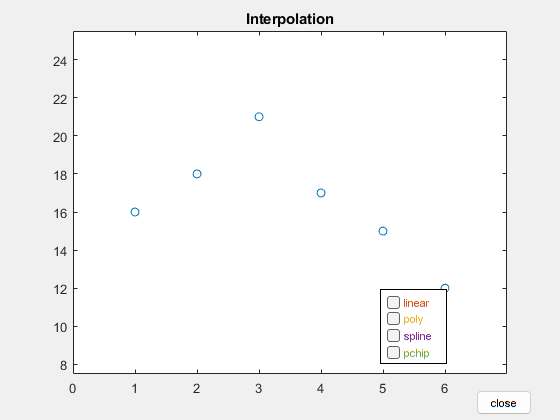

clearvars; 
x = 1:6;
y = [16 18 21 17 15 12];
interpgui(x,y)

**Diferències entre spline i pchip**

clearvars;
x = 1: 8;
y = zeros (1,8);
y (4) = 1;
interpgui(x, y)

### Funció de MATLAB® 

Per veure totes les possibilitats d'interpolació en MATLAB® consulteu la pàgina [interpolación](https://es.mathworks.com/help/matlab/interpolation.html) y més concretament la pàgina de la comanda [interp1](https://es.mathworks.com/help/matlab/ref/interp1.html), per obtenir un polinomi interpolador a trossos. Resum de de la comanda. 

Baixeu-vos del campus ***InterpolationofCoarselySampledSineFunctionExample.mlx, ***és el primer exemple de la documentació. Apreneu com s'usa la comanda interp1 per a obtenir els valors de l'spline lineal i els valors de l'spline cúbic. 

% openExample('matlab/InterpolationofCoarselySampledSineFunctionExample')

**INTERPOLACIÓ I EXTRAPOLACIÓ**

Baixeu-vos del campus ***ExtrapolationUsingTwoDifferentMethodsExample.mlx*** . Aquest codi és de la documentació. Apreneu com s'usa la comanda interp1 per a obtenir els valors de l'spline per avaluar punts que es troben fora del domini de x.

% openExample('matlab/ExtrapolationUsingTwoDifferentMethodsExample')

## $\bullet$PRACTIQUEM ....

### Exercici 6

Per la taula de dades següent es demana la representació gràfica :

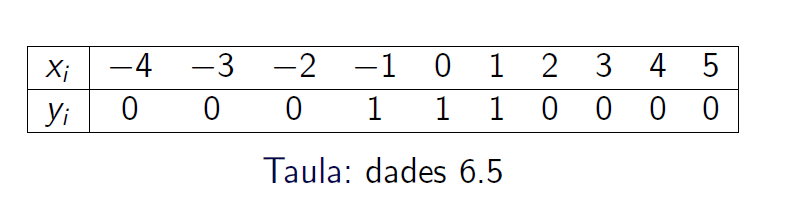

x = -4:5; y = [0 0 0 1 1 1 0 0 0 0];
disp([x; y])

    -4    -3    -2    -1     0     1     2     3     4     5
     0     0     0     1     1     1     0     0     0     0



 xq = linspace(min(x), max(x), 100);

- Del polinomi interpolador

p = polyfit(x, y, numel(x) - 1);
x_poli = linspace(min(x), max(x), 100);
y_poli = polyval(p, x_poli);

- Del spline lineal

y_lineal = interp1(x, y, xq, 'linear');

- Del spline natural

y_cubica = interp1(x, y, xq, 'pchip');

- Del spline shape-preserving

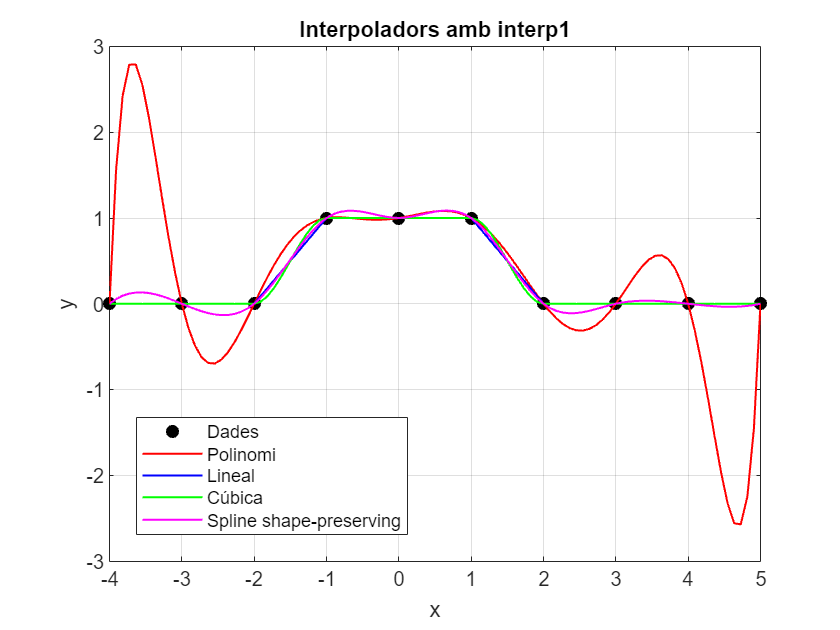

y_shape = interp1(x, y, xq, 'spline');

figure
plot(x, y, 'ko', 'MarkerFaceColor', 'k', 'DisplayName', 'Dades');
hold on;
plot(x_poli, y_poli, 'r-', 'LineWidth', 1, 'DisplayName', 'Polinomi');
plot(xq, y_lineal, 'b-', 'LineWidth', 1, 'DisplayName', 'Lineal');
plot(xq, y_cubica, 'g-', 'LineWidth', 1, 'DisplayName', 'Cúbica');
plot(xq, y_shape, 'm-', 'LineWidth', 1, 'DisplayName', 'Spline shape-preserving');
hold off;
legend('Location', 'best');
xlabel('x');
ylabel('y');
title('Interpoladors amb interp1');
grid on;

### Exercici 7

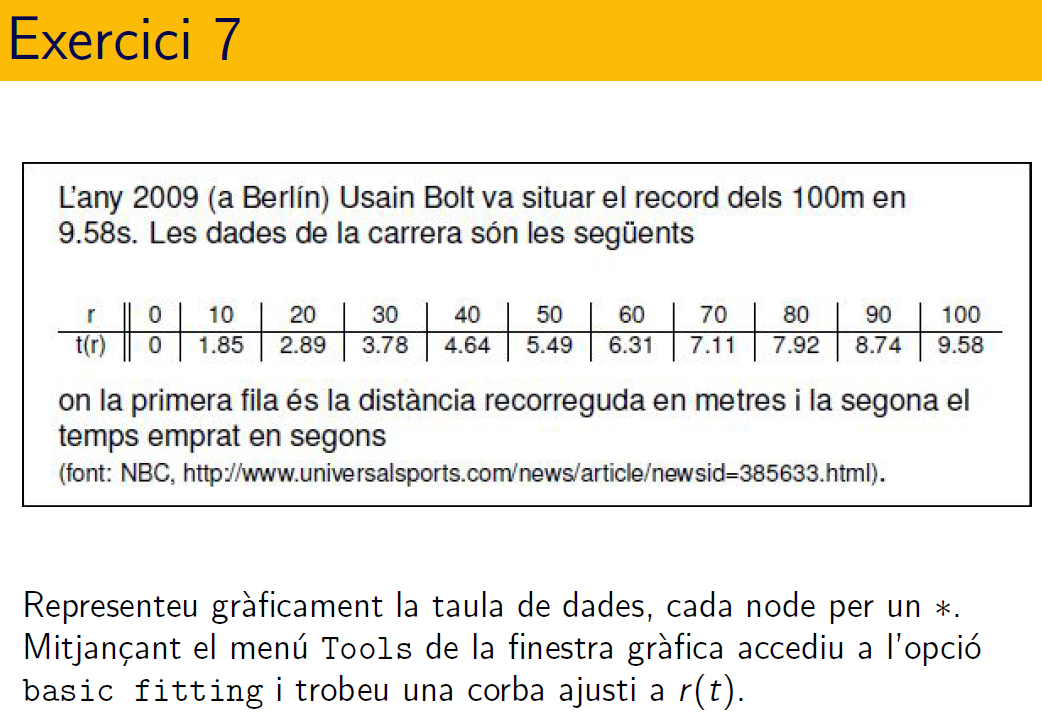

### Exercici 8

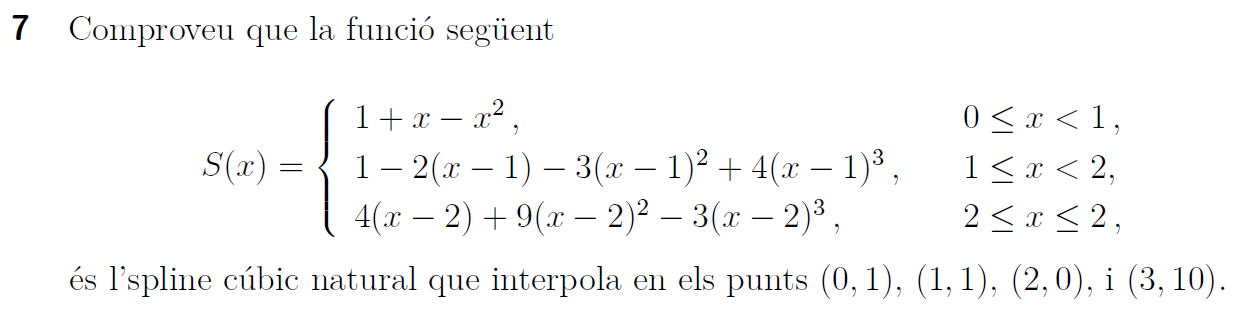

## $\bullet$RECORDEM ... Bloc 3 

### Ajust de dades

### Funció de MATLAB®  

Els coeficients dels polinomis per mínims quadrats es poden obtenir amb polyfit, i els valors aproximats amb polyval. Consulteu [polyfit](https://es.mathworks.com/help/matlab/ref/polyfit.html)

openExample('matlab/FitPolynomialToSetOfPointsExample')

## $\bullet$PRACTIQUEM ....

### Exercici 9

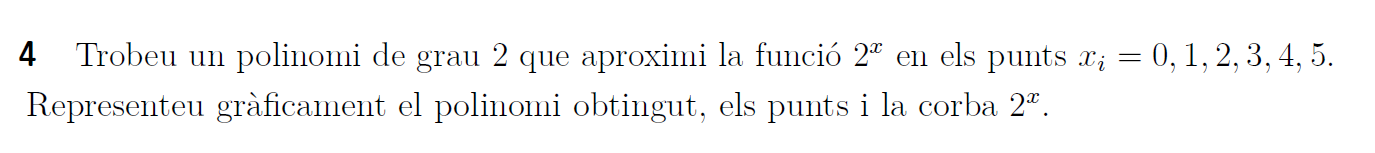

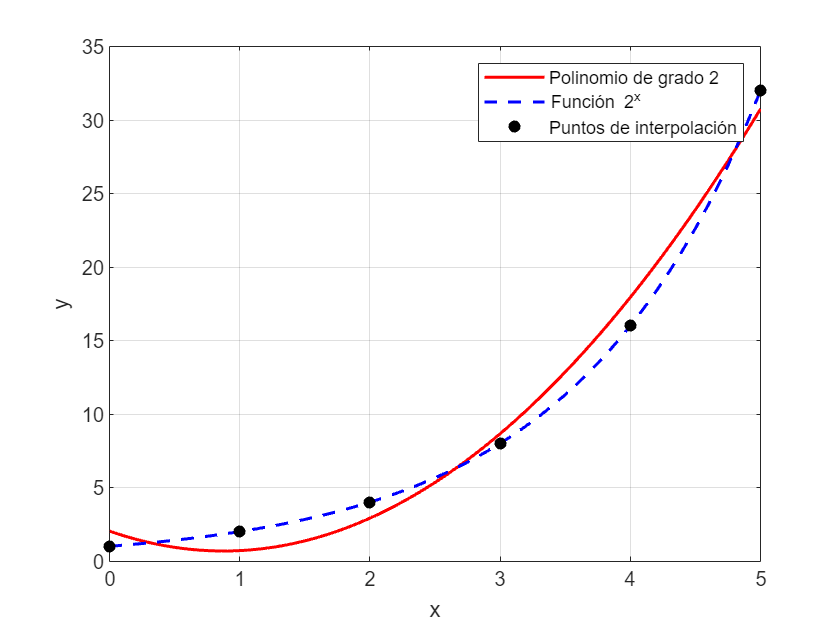

% Datos
xi = 0:5;
yi = 2 .^ xi;

% Aproximación por un polinomio de grado 2
p = polyfit(xi, yi, 2);

% Evaluar el polinomio en un conjunto de puntos
x_plot = linspace(0, 5, 100);
y_plot = polyval(p, x_plot);

% Función real 2^x
y_real = 2 .^ x_plot;

% Gráfica
figure
plot(x_plot, y_plot, 'r-', 'LineWidth', 1.5);
hold on;
plot(x_plot, y_real, 'b--', 'LineWidth', 1.5);
scatter(xi, yi, 'ko', 'filled');
xlabel('x');
ylabel('y');
legend('Polinomio de grado 2', 'Función 2^x', 'Puntos de interpolación');
grid on;

### Exercici 10.   

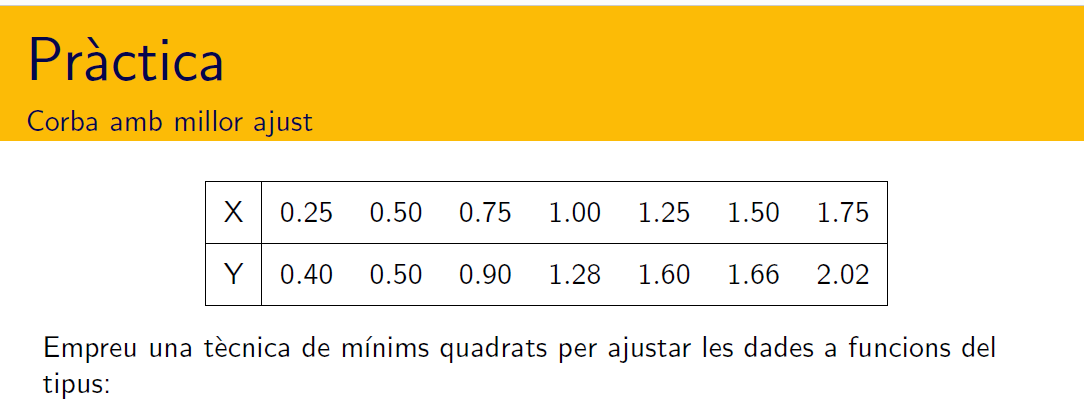

clearvars; clf; format shortG
x = 0.25:0.25:1.75;
y = [0.4,0.5 0.9 1.28 1.60 1.66 2.02];
disp([x;y]')

         0.25          0.4
          0.5          0.5
         0.75          0.9
            1         1.28
         1.25          1.6
          1.5         1.66
         1.75         2.02



- recta

 X = [0.25 0.50 0.75 1.00 1.25 1.50 1.75];
Y = [0.40 0.50 0.90 1.28 1.60 1.66 2.02];

% Ajuste lineal
p1 = polyfit(X, Y, 1);
a0 = p1(2);
a1 = p1(1);

% Vector residuo
Y_est1 = polyval(p1, X);
resid1 = Y - Y_est1;

- Polinomi de grau 4

 % Ajuste polinomial de grado 4
p2 = polyfit(X, Y, 4);

% Vector residuo
Y_est2 = polyval(p2, X);
resid2 = Y - Y_est2;


- Corba $y = ax^{b}  \rightarrow \ln(y)=b\ln(x)+\ln(a) \rightarrow Y = A_1X+A_0$

% Linealización: ln(y) = ln(a) + αln(x)
lnX = log(X);
lnY = log(Y);

% Ajuste lineal en el espacio logarítmico
p3 = polyfit(lnX, lnY, 1);
alpha = p3(1);
a = exp(p3(2));

% Vector residuo
Y_est3 = a * X .^ alpha;
resid3 = Y - Y_est3;


ECM1 = mean(resid1 .^ 2);
ECM2 = mean(resid2 .^ 2);
ECM3 = mean(resid3 .^ 2);

[min_ECM, idx] = min([ECM1, ECM2, ECM3]);


- Gràfica

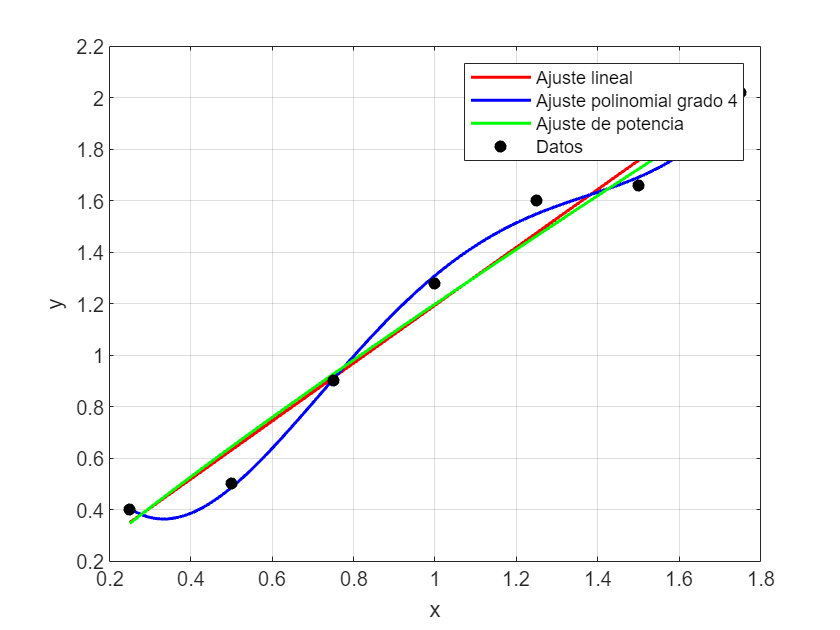

x_plot = linspace(0.25, 1.75, 100);
y_est1_plot = polyval(p1, x_plot);
y_est2_plot = polyval(p2, x_plot);
y_est3_plot = a * x_plot .^ alpha;

figure;
plot(x_plot, y_est1_plot, 'r-', 'LineWidth', 1.5);
hold on;
plot(x_plot, y_est2_plot, 'b-', 'LineWidth', 1.5);
plot(x_plot, y_est3_plot, 'g-', 'LineWidth', 1.5);
scatter(X, Y, 'ko', 'filled');
xlabel('x');
ylabel('y');
legend('Ajuste lineal', 'Ajuste polinomial grado 4', 'Ajuste de potencia', 'Datos');
grid on;

#### Exercici 11.  Sistema  sobredeterminat

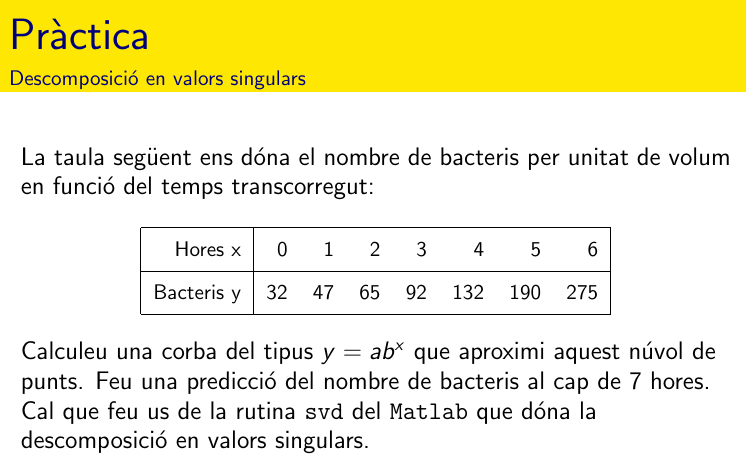

X = [0 1 2 3 4 5 6];
Y = [32 47 65 92 132 190 275];

% Aplicar logaritmo a los datos de Y
lnY = log(Y);

% Crear la matriz A y el vector B
A = [ones(length(X), 1), X'];
B = lnY';

% Descomposición de valores singulares
[U, S, V] = svd(A);

% Calcular los coeficientes a y b
coeff = V * (S \ (U' * B));
lna = coeff(1);
lnb = coeff(2);

% Obtener a y b a partir de los logaritmos
a = exp(lna);
b = exp(lnb);

% Predecir el número de bacterias en 7 horas
x_pred = 7;
y_pred = a * b^x_pred

y_pred =        387.27


`document preparat per M. Àngela Grau Gotés - maig 2022`